clc; clear all; close all; 


## Demonstrating R-PCA

This is a synthetic low rank matrix, with 200 observations and 300 variables. The actual rank of the matrix is 3. We want to divide this into the low-rank matrix and the sparse noise.

rng(7);

m = 200; n = 300; rtrue = 3;
U = randn(m, rtrue);
V = randn(n, rtrue);
L0 = U * V.';                         

rho = 0.05;                           
S0 = sprandn(m, n, rho);
S0 = full(S0) .* (10 * rand(m,n));    

X = L0 + S0;                          

[Lb, Sb, info] = rpca_pcp(X, [], [], 1e-5, 1000, true);

Iter    1: relRes = 8.924e-01, rank(L) = 3, nnz(S) = 135
Iter   10: relRes = 4.029e-02, rank(L) = 3, nnz(S) = 2055
Iter   20: relRes = 1.578e-02, rank(L) = 3, nnz(S) = 2430
Iter   30: relRes = 9.126e-03, rank(L) = 3, nnz(S) = 2574
Iter   40: relRes = 5.799e-03, rank(L) = 3, nnz(S) = 2663
Iter   50: relRes = 4.293e-03, rank(L) = 3, nnz(S) = 2711
Iter   60: relRes = 3.276e-03, rank(L) = 3, nnz(S) = 2748
Iter   70: relRes = 2.640e-03, rank(L) = 3, nnz(S) = 2774
Iter   80: relRes = 2.079e-03, rank(L) = 3, nnz(S) = 2800
Iter   90: relRes = 1.774e-03, rank(L) = 3, nnz(S) = 2814
Iter  100: relRes = 1.585e-03, rank(L) = 3, nnz(S) = 2823
Iter  110: relRes = 1.297e-03, rank(L) = 3, nnz(S) = 2838
Iter  120: relRes = 1.095e-03, rank(L) = 3, nnz(S) = 2848
Iter  130: relRes = 9.655e-04, rank(L) = 3, nnz(S) = 2854
Iter  140: relRes = 8.817e-04, rank(L) = 3, nnz(S) = 2860
Iter  150: relRes = 7.554e-04, rank(L) = 3, nnz(S) = 2866
Iter  160: relRes = 6.847e-04, rank(L) = 3, nnz(S) = 2870
Iter  170: relR


relErrL = norm(Lb - L0, 'fro') / norm(L0, 'fro');
relErrS = norm(Sb - S0, 'fro') / norm(S0, 'fro');

fprintf('Relative error L: %.3e, S: %.3e, iters: %d, time: %.2fs\n', ...
    relErrL, relErrS, info.iters, info.time);

Relative error L: 1.137e-05, S: 9.141e-05, iters: 1000, time: 410.16s


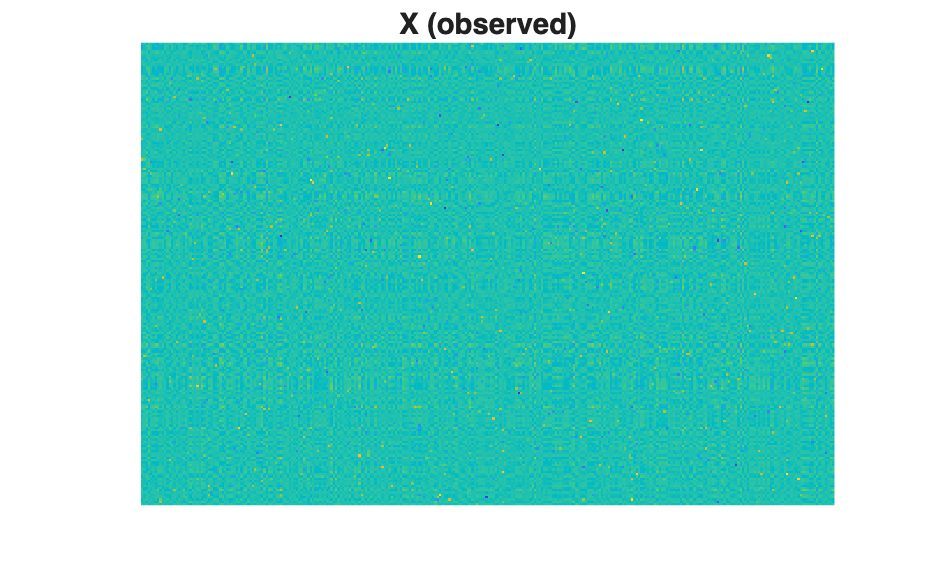


figure; 
imagesc(X); axis image off; title('X (observed)');

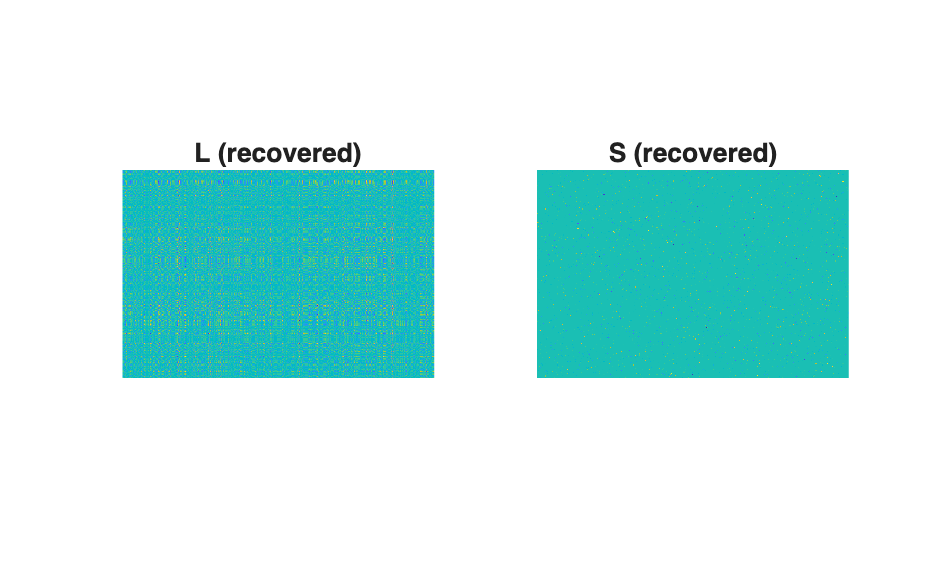


figure;
subplot(1,2,1); imagesc(Lb); axis image off; title('L (recovered)');
subplot(1,2,2); imagesc(Sb); axis image off; title('S (recovered)');

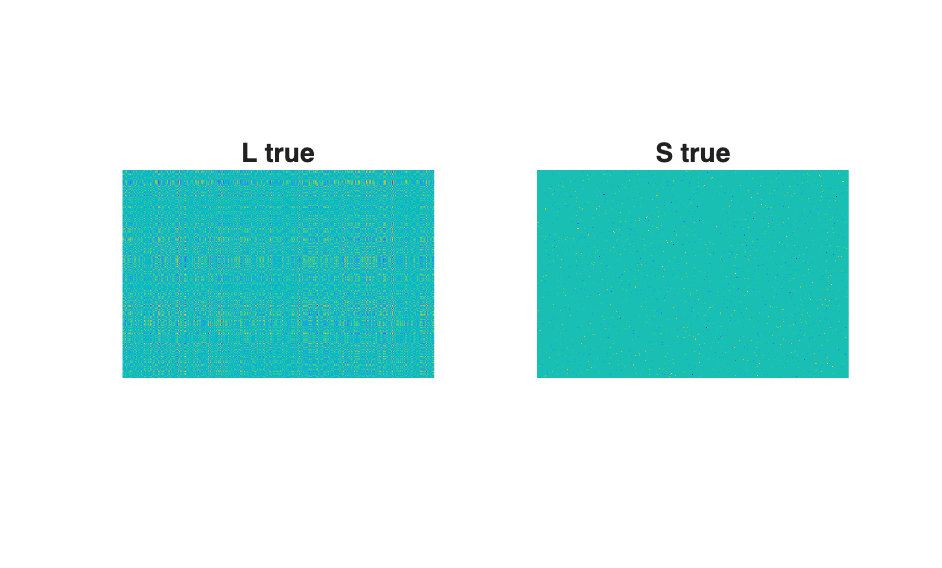


figure;
subplot(1,2,1); imagesc(L0); axis image off; title('L true');
subplot(1,2,2); imagesc(S0); axis image off; title('S true');

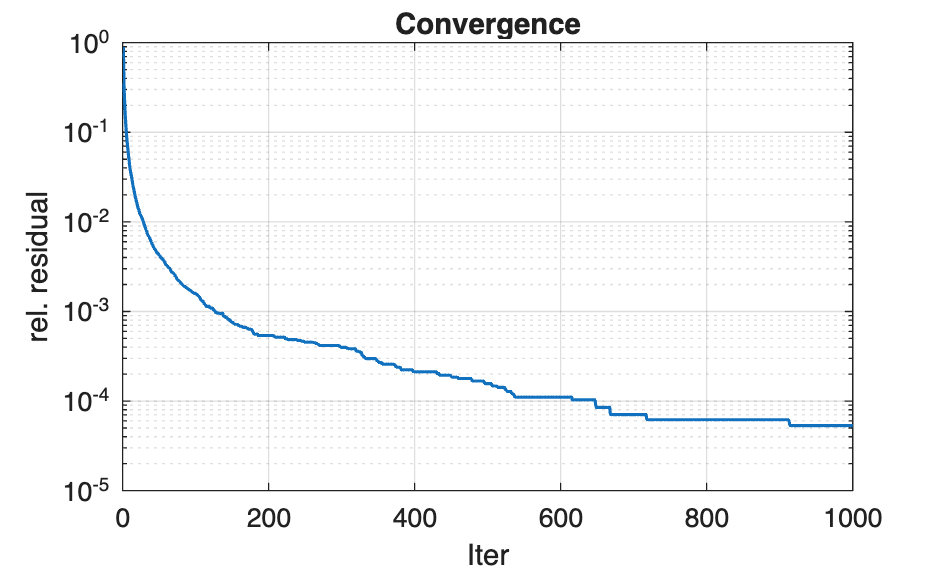


figure;
semilogy(info.relRes,'LineWidth',1.2);
grid on; title('Convergence'); xlabel('Iter'); ylabel('rel. residual');

colormap parula;

## Background removal


% Files expected in current folder:
%   - with.jpg                  (object + background)
%   - without_*.jpg             (several background-only frames)
% Also requires rpca_pcp.m in path.

clear; clc; close all;

useColor = true;     % false = grayscale (faster)
maxBG    = 50;       
doCenter = true;     
minObjPx = 50;       

Iw_org = im2double(imread('IMG_8187.jpg'))

Iw_org = Iw_org(:,:,1) =

  Columns 1 through 3276

    0.9216    0.9020    0.8863    0.9216    0.9333    0.9098    0.9255    0.9569    0.9098    0.8824    0.8863    0.8980    0.8863    0.8745    0.8824    0.8863    0.9059    0.9059    0.9137    0.9294    0.8980    0.8863    0.9098    0.8745    0.8706    0.8980    0.9098    0.9020    0.9176    0.9333    0.9176    0.8941    0.8824    0.8941    0.9176    0.9373    0.9333    0.9255    0.9137    0.8980    0.9216    0.9412    0.9490    0.9333    0.9294    0.9451    0.9412    0.9059    0.9804    0.9490    0.9490    0.9490    0.9255    0.9098    0.9176    0.9255    0.9608    0.9686    0.9451    0.9059    0.9020    0.9176    0.9137    0.9059    0.8667    0.8824    0.9294    0.9137    0.9176    0.9059    0.9176    0.9412    0.9216    0.9020    0.8902    0.8941    0.9216    0.9137    0.9059    0.9608    0.9647    0.9294    0.9216    0.9137    0.8745    0.8588    0.8667    0.8627    0.8275    0.8627    0.8824    0.9020    0.8863    0.8706    0.89

Iw = imresize(Iw_org, [200,200])

Iw = Iw(:,:,1) =

    0.8838    0.8604    0.8588    0.8244    0.7869    0.7708    0.7710    0.7712    0.7818    0.8043    0.8363    0.8389    0.8429    0.8384    0.8490    0.8337    0.8235    0.8265    0.8391    0.8185    0.8105    0.8230    0.8086    0.8172    0.8266    0.8111    0.8139    0.8045    0.8004    0.8126    0.7999    0.7866    0.7963    0.7905    0.8193    0.8190    0.8219    0.8193    0.8190    0.8117    0.8189    0.8409    0.8793    0.8638    0.8577    0.8512    0.8534    0.8543    0.8658    0.8442    0.8138    0.8213    0.8235    0.8401    0.8295    0.8040    0.7862    0.8135    0.8458    0.8786    0.8786    0.8841    0.8794    0.8806    0.8871    0.8831    0.8617    0.8496    0.8424    0.8476    0.8580    0.8385    0.8314    0.8400    0.8429    0.8554    0.8755    0.8944    0.8933    0.8875    0.8727    0.8820    0.8840    0.8698    0.8655    0.8675    0.8676    0.8781    0.8603    0.8433    0.8482    0.8923    0.9112    0.9008    0.8916    0.8913    0.8740    0.8799  

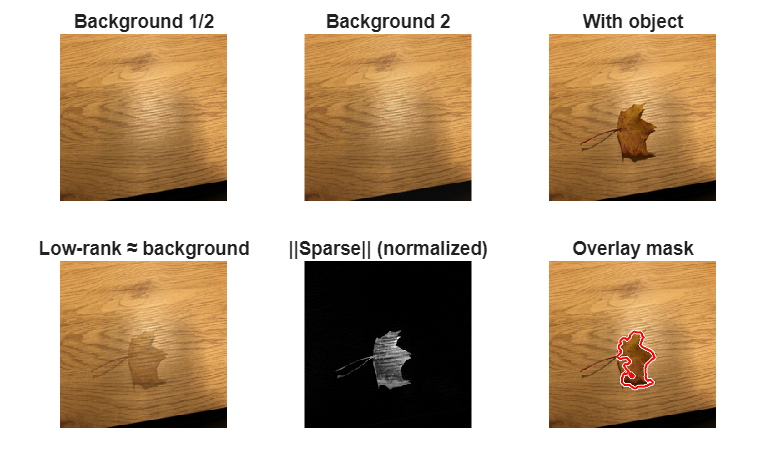


if size(Iw,3) == 1, Iw = repmat(Iw,[1 1 3]); end  % force RGB for consistency
[H,W,~] = size(Iw);

% bgList = dir('IMG_8188.jpg');
% if isempty(bgList)
%     bgList = dir('without*.jpg'); 
% end
% 
% [~,ix] = sort({bgList.name});
% bgList = bgList(ix);
% if ~isempty(maxBG), bgList = bgList(1:min(maxBG, numel(bgList))); end

% the images need to be the same size!
% also, don't move the camera. we are doing pixel-to-pixel comparisons
BG = zeros(H, W, 3, 2);
for i = 1:2
    Ii = im2double(imread('IMG_8188.jpg'));
    if i == 2, Ii = imnoise(Ii, 'gaussian', 0, 0.01); end
    if size(Ii,3) == 1, Ii = repmat(Ii,[1 1 3]); end
    if any(size(Ii,1:2) ~= [H W])
        Ii = imresize(Ii, [H W]);
    end
    BG(:,:,:,i) = Ii;
end

% Columns 1..NB: backgrounds; last column NB+1: with-object frame
NB = size(BG,4);
if useColor
    X = reshape(BG, [], NB);             % stack RGB channels vertically
    X = [X, reshape(Iw, [], 1)];
else
    BGg = rgb2gray(BG);
    Iwg = rgb2gray(Iw);
    X = reshape(BGg, [], NB);
    X = [X, Iwg(:)];
end

if doCenter
    mu = mean(X, 2);
    Xc = X - mu;
else
    mu = 0;
    Xc = X;
end

[L, S] = rpca_pcp(Xc);  % lambda/mu are on default

L_with = L(:, end) + mu;   
S_with = S(:, end);         

if useColor
    Lk = reshape(L_with, [H W 3]);
    Sk = reshape(S_with, [H W 3]);
    Smag = sqrt(sum(Sk.^2, 3));
else
    Lk = reshape(L_with, [H W]);
    Sk = reshape(S_with, [H W]);
    Smag = abs(Sk);
end

SmagN = mat2gray(Smag);
try
    T = graythresh(SmagN);                    
    mask = imbinarize(SmagN, T);
catch
    medv = median(Smag(:));
    madv = median(abs(Smag(:)-medv)) + eps;
    T = medv + 3*madv;
    mask = Smag > T;
end

if exist('imopen','file')
    mask = imopen(mask, strel('disk', 2));
    mask = imclose(mask, strel('disk', 2));
    mask = bwareaopen(mask, minObjPx);
end

figure('Name','RPCA multi-background','Color','w');
tiledlayout(2,3,'Padding','compact','TileSpacing','compact');

nexttile; imshow(BG(:,:,:,1)); title(sprintf('Background 1/%d', NB));
nexttile; imshow(BG(:,:,:,min(2,NB))); title('Background 2');
nexttile; imshow(Iw); title('With object');

nexttile; imshow(Lk, []); title('Low-rank ≈ background');
nexttile; imshow(SmagN, []); title('||Sparse|| (normalized)');
nexttile; imshow(Iw); hold on; visboundaries(mask, 'LineWidth', 1);
title('Overlay mask'); hold off;

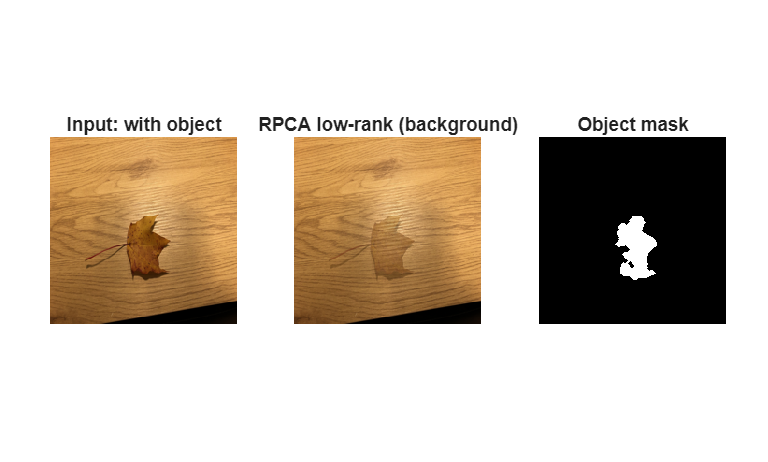



figure('Color','w');
tiledlayout(1,3,'Padding','compact','TileSpacing','compact');
nexttile; imshow(Iw); title('Input: with object');
nexttile; imshow(Lk, []); title('RPCA low-rank (background)');
nexttile; imshow(mask); title('Object mask');

## Functions

function G = toGrayND(X)
% Convert RGB to grayscale for 3-D (H x W x 3) or 4-D (H x W x 3 x N) arrays.
% If already grayscale, returns X unchanged.

    nd = ndims(X);
    if nd == 2
        G = X;                         % already gray H x W
    elseif nd == 3
        if size(X,3) == 1
            G = X;                     % already gray H x W x 1
        else
            G = 0.298936 * X(:,:,1) + 0.587043 * X(:,:,2) + 0.114021 * X(:,:,3);
        end
    elseif nd == 4
        assert(size(X,3) == 3, 'Expected RGB in 3rd dim for 4-D input');
        G = 0.298936 * X(:,:,1,:) + 0.587043 * X(:,:,2,:) + 0.114021 * X(:,:,3,:);
    else
        error('Unsupported array size for grayscale conversion.');
    end
end

function tf = hasIPT()
% Quick check for Image Processing Toolbox availability
    tf = ~isempty(ver('images'));
end

function [Lk, SmagN, mask] = run_rpca_and_mask(BGstack, Iwith, useColor, doCenter, minObjPx)
    [H,W,~] = size(Iwith);
    NB = size(BGstack,4);
    if useColor
        X = reshape(BGstack, [], NB);
        X = [X, reshape(Iwith, [], 1)];
    else
        BGg = toGrayND(BGstack);      
        Iwg = toGrayND(Iwith);          
    end
    if doCenter
        mu = mean(X,2);
        Xc = X - mu;
    else
        mu = 0;
        Xc = X;
    end

    [L, S] = rpca_pcp(Xc);     % defaults are robust
    L_with = L(:, end) + mu;   % add mean back if centered
    S_with = S(:, end);

    if useColor
        Lk = reshape(L_with, [H W 3]);
        Sk = reshape(S_with, [H W 3]);
        Smag = sqrt(sum(Sk.^2, 3));
    else
        Lk = reshape(L_with, [H W]);
        Sk = reshape(S_with, [H W]);
        Smag = abs(Sk);
    end
    SmagN = mat2gray(Smag);

    % Threshold: Otsu if available, else robust MAD
    if exist('graythresh','file')
        T = graythresh(SmagN);
        mask = imbinarize(SmagN, T);
    else
        medv = median(Smag(:));
        madv = median(abs(Smag(:) - medv)) + eps;
        mask = Smag > (medv + 3*madv);
    end

    if exist('imopen','file')
        mask = imopen(mask, strel('disk',2));
        mask = imclose(mask, strel('disk',2));
        mask = bwareaopen(mask, minObjPx);
    end
end
